## (a) Rotating Magnetic Field

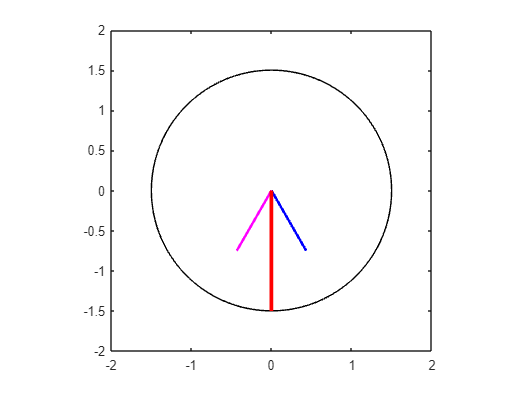

% If a three-phase set of currents, each of equal magnitude and differing in phase by 120 flows in a three-phase,
% then it will produce a rotating magnetic field of constant magnitude. 
% Calculate the net magnetic field produced by a three-phase stator.  
% Set up the basic conditions
bmax = 1; % Normalize bmax to 1
freq = 60; % 60 Hz
w = 2*pi*freq; % angular velocity (rad/s) 
% First , generate the three component magnetic fi e l ds 
t = 0:1/6000:1/60; 
Baa = sin(w*t) .* (cos(0) + j*sin(0));
Bbb = sin(w*t - 2*pi/3) * (cos(2*pi/3) + j*sin(2*pi /3)) ; 
Bcc = sin(w*t + 2*pi/3) * (cos(-2*pi/3) + j*sin(-2*pi /3)) ; 
% Calculate Bnet 
Bnet = Baa + Bbb + Bcc; 
% Calculate a circle representing the expected maximum value of Bnet 
circle = 1.5 * (cos(w*t ) + j *sin (w*t) ) ; 
% Plot the magnitude and direction of the resulting magnetic fields. Note that
% Baa is black, Bbb is blue, Bcc is magenta, and Bnet is red. 
for ii = 1:length (t) 
% Plot the reference circle 
 plot(circle,'k'); 
hold on; 
% Plot the four magnetic fields
plot([0 real(Baa(ii))],[0 imag(Baa(ii))],'k','LineWidth',2); 
plot([0 real(Bbb(ii))],[0 imag(Bbb(ii))],'b','LineWidth',2); 
plot([0 real(Bcc(ii))],[0 imag(Bcc(ii))],'m','LineWidth',2); 
plot([0 real(Bnet(ii))],[0 imag(Bnet(ii))],'r','LineWidth',3); 
axis square; 
axis([-2 2 -2 2]); 
drawnow;
hold off;
end

## (a) (i) What will happen when the current in any two of the three coils is swapped?

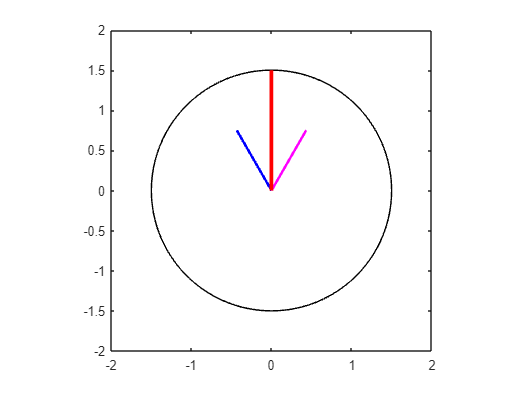

bmax = 1; % Normalize bmax to 1
freq = 60; % 60 Hz
w = 2*pi*freq; % angular velocity (rad/s) 
% First , generate the three component magnetic fields 
t = 0:1/6000:1/60; 
Baa = sin(w*t) .* (cos(0) + j*sin(0));
Bbb = sin(w*t + 2*pi/3) * (cos(2*pi/3) + j*sin(2*pi /3)) ; 
Bcc = sin(w*t - 2*pi/3) * (cos(-2*pi/3) + j*sin(-2*pi /3)) ; 
% Calculate Bnet 
Bnet = Baa + Bbb + Bcc; 
% Calculate a circle representing the expected maximum value of Bnet 
circle = 1.5 * (cos(w*t ) + j *sin (w*t) ) ;
% Plot the magnitude and direction of the resulting magnetic fields. Note that
% Baa is black, Bbb is blue, Bcc is magenta, and Bnet is red. 
for ii = 1:length (t) 
% Plot the reference circle 
 plot(circle,'k'); 
hold on; 
% Plot the four magnetic fields
plot([0 real(Baa(ii))],[0 imag(Baa(ii))],'k','LineWidth',2); 
plot([0 real(Bbb(ii))],[0 imag(Bbb(ii))],'b','LineWidth',2); 
plot([0 real(Bcc(ii))],[0 imag(Bcc(ii))],'m','LineWidth',2); 
plot([0 real(Bnet(ii))],[0 imag(Bnet(ii))],'r','LineWidth',3); 
axis square; 
axis([-2 2 -2 2]); 
drawnow;
hold off;
end

## (a) (ii) What would be the effect of variation of the amplitude of currents in each phase?

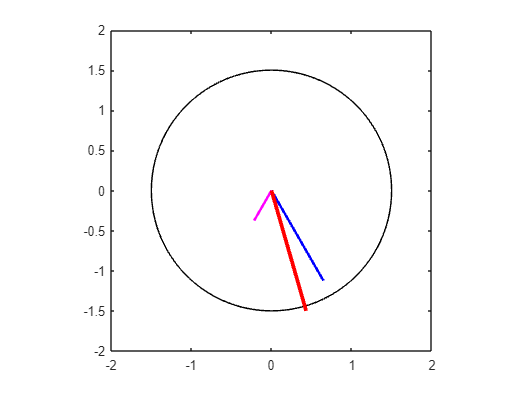

freq = 60; % 60 Hz
w = 2*pi*freq; % angular velocity (rad/s) 
% First , generate the three component magnetic fields 
% [SWAP B & C]
t = 0:1/6000:1/60; 
Baa = 1*sin(w*t) .* (cos(0) + j*sin(0));
Bbb = 1.5*sin(w*t - 2*pi/3) * (cos(2*pi/3) + j*sin(2*pi /3)) ; 
Bcc = 0.5*sin(w*t + 2*pi/3) * (cos(-2*pi/3) + j*sin(-2*pi /3)) ; 
% Calculate Bnet 
Bnet = Baa + Bbb + Bcc; 
% Calculate a circle representing the expected maximum value of Bnet 
circle = 1.5 * (cos(w*t ) + j *sin (w*t) ) ; 
% Plot the magnitude and direction of the resulting magnetic fields. Note that
% Baa is black, Bbb is blue, Bcc is magenta, and Bnet is red. 
for ii = 1:length (t) 
% Plot the reference circle 
 plot(circle,'k'); 
hold on; 
% Plot the four magnetic fields
plot([0 real(Baa(ii))],[0 imag(Baa(ii))],'k','LineWidth',2); 
plot([0 real(Bbb(ii))],[0 imag(Bbb(ii))],'b','LineWidth',2); 
plot([0 real(Bcc(ii))],[0 imag(Bcc(ii))],'m','LineWidth',2); 
plot([0 real(Bnet(ii))],[0 imag(Bnet(ii))],'r','LineWidth',3); 
axis square; 
axis([-2 2 -2 2]); 
drawnow;
hold off;
end

## (a) (iii) What would be the effect of variations in phase angles?

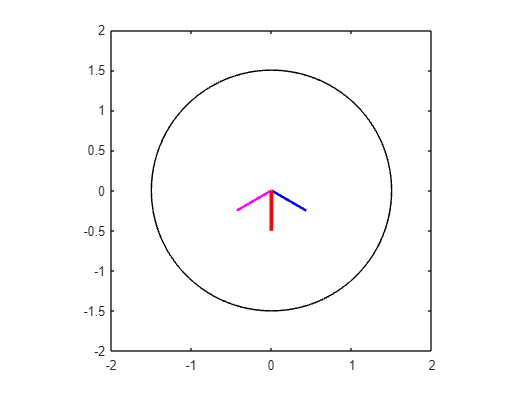

freq = 60; % 60 Hz
w = 2*pi*freq; % angular velocity (rad/s) 
% First , generate the three component magnetic fields 
t = 0:1/6000:1/60; 
Baa = sin(w*t) .* (cos(0) + j*sin(0));
Bbb = sin(w*t - 5*pi/6) * (cos(5*pi/6) + j*sin(5*pi/6)) ; 
Bcc = sin(w*t + 5*pi/6) * (cos(-5*pi/6) + j*sin(-5*pi/6)) ; 
% Calculate Bnet 
Bnet = Baa + Bbb + Bcc; 
% Calculate a circle representing the expected maximum value of Bnet 
circle = 1.5 * (cos(w*t ) + j *sin (w*t) ) ; 
% Plot the magnitude and direction of the resulting magnetic fields. Note that
% Baa is black, Bbb is blue, Bcc is magenta, and Bnet is red. 
for ii = 1:length (t) 
% Plot the reference circle 
 plot(circle,'k'); 
hold on; 
% Plot the four magnetic fields
plot([0 real(Baa(ii))],[0 imag(Baa(ii))],'k','LineWidth',2); 
plot([0 real(Bbb(ii))],[0 imag(Bbb(ii))],'b','LineWidth',2); 
plot([0 real(Bcc(ii))],[0 imag(Bcc(ii))],'m','LineWidth',2); 
plot([0 real(Bnet(ii))],[0 imag(Bnet(ii))],'r','LineWidth',3); 
axis square; 
axis([-2 2 -2 2]); 
drawnow;
hold off;
end

## (a) (iv) What would be the effect of

## 1) increasing the value of electrical frequency?

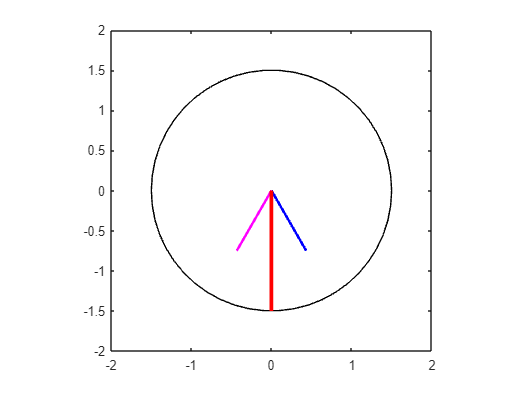

freq = 120;
w = 2*pi*freq;
% First , generate the three component magnetic fields 
t = 0:1/6000:1/60; 
Baa = sin(w*t) .* (cos(0) + j*sin(0));
Bbb = sin(w*t - 2*pi/3) * (cos(2*pi/3) + j*sin(2*pi/3)) ; 
Bcc = sin(w*t + 2*pi/3) * (cos(-2*pi/3) + j*sin(-2*pi/3)) ;
% Calculate Bnet 
Bnet = Baa + Bbb + Bcc; 
% Calculate a circle representing the expected maximum value of Bnet 
circle = 1.5 * (cos(w*t ) + j *sin (w*t) ) ; 
% Plot the magnitude and direction of the resulting magnetic fields. Note that
% Baa is black, Bbb is blue, Bcc is magenta, and Bnet is red. 
for ii = 1:length (t) 
% Plot the reference circle 
 plot(circle,'k'); 
hold on; 
% Plot the four magnetic fields
plot([0 real(Baa(ii))],[0 imag(Baa(ii))],'k','LineWidth',2); 
plot([0 real(Bbb(ii))],[0 imag(Bbb(ii))],'b','LineWidth',2); 
plot([0 real(Bcc(ii))],[0 imag(Bcc(ii))],'m','LineWidth',2); 
plot([0 real(Bnet(ii))],[0 imag(Bnet(ii))],'r','LineWidth',3); 
axis square; 
axis([-2 2 -2 2]); 
drawnow;
hold off;
end

## (a) (iv) 2) decreasing the value of electrical frequency?

freq = 30;
w = 2*pi*freq;
% First , generate the three component magnetic fields 
t = 0:1/6000:1/60; 
Baa = sin(w*t) .* (cos(0) + j*sin(0));
Bbb = sin(w*t - 2*pi/3) * (cos(2*pi/3) + j*sin(2*pi/3)) ; 
Bcc = sin(w*t + 2*pi/3) * (cos(-2*pi/3) + j*sin(-2*pi/3)) ;
% Calculate Bnet 
Bnet = Baa + Bbb + Bcc; 
% Calculate a circle representing the expected maximum value of Bnet 
circle = 1.5 * (cos(2*w*t ) + j *sin (2*w*t) ) ; 
% Plot the magnitude and direction of the resulting magnetic fields. Note that
% Baa is black, Bbb is blue, Bcc is magenta, and Bnet is red. 
for ii = 1:length (t) 
% Plot the reference circle 
 plot(circle,'k'); 
hold on; 
% Plot the four magnetic fields
plot([0 real(Baa(ii))],[0 imag(Baa(ii))],'k','LineWidth',2); 
plot([0 real(Bbb(ii))],[0 imag(Bbb(ii))],'b','LineWidth',2); 
plot([0 real(Bcc(ii))],[0 imag(Bcc(ii))],'m','LineWidth',2); 
plot([0 real(Bnet(ii))],[0 imag(Bnet(ii))],'r','LineWidth',3); 
axis square; 
axis([-2 2 -2 2]); 
drawnow;
hold off;
end

## (a) (v) What would be the effect of incorporating more sets of three-phase winding, i.e.,increasing the number of magnetic poles?

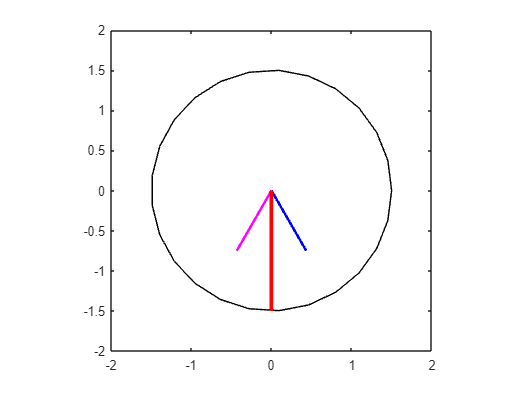

freq = 60;
% No. of poles=p
p=4;
w = 2*pi*freq*p;
% First , generate the three component magnetic fields 
t = 0:1/6000:1/60; 
Baa = sin(w*t) .* (cos(0) + j*sin(0));
Bbb = sin(w*t - 2*pi/3) * (cos(2*pi/3) + j*sin(2*pi/3)) ; 
Bcc = sin(w*t + 2*pi/3) * (cos(-2*pi/3) + j*sin(-2*pi/3)) ;
% Calculate Bnet 
Bnet = Baa + Bbb + Bcc; 
% Calculate a circle representing the expected maximum value of Bnet 
circle = 1.5 * (cos(w*t ) + j *sin (w*t) ) ; 
% Plot the magnitude and direction of the resulting magnetic fields. Note that
% Baa is black, Bbb is blue, Bcc is magenta, and Bnet is red. 
for ii = 1:length (t) 
% Plot the reference circle 
 plot(circle,'k'); 
hold on; 
% Plot the four magnetic fields
plot([0 real(Baa(ii))],[0 imag(Baa(ii))],'k','LineWidth',2); 
plot([0 real(Bbb(ii))],[0 imag(Bbb(ii))],'b','LineWidth',2); 
plot([0 real(Bcc(ii))],[0 imag(Bcc(ii))],'m','LineWidth',2); 
plot([0 real(Bnet(ii))],[0 imag(Bnet(ii))],'r','LineWidth',3); 
axis square; 
axis([-2 2 -2 2]); 
drawnow;
hold off;
end

## (b) Interaction of the magnetic field produced by a current carrying one-loop rotor with the rotating magnetic field of the three-phase stator windings.

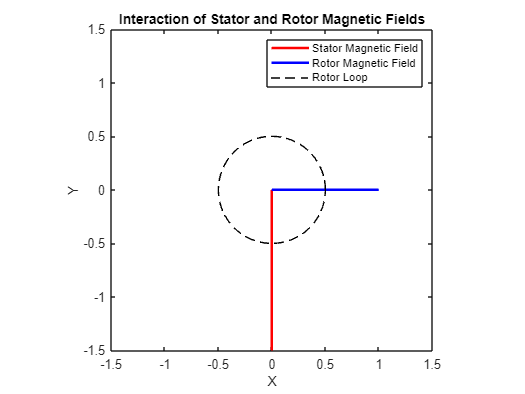

% Set up basic parameters
bmax = 1; % Normalize bmax to 1
freq = 60; % 60 Hz
w = 2*pi*freq; % angular velocity (rad/s)
t = 0:1/6000:1/60;

% Generate the three component magnetic fields of the stator
Baa = sin(w*t) .* (cos(0) + 1i*sin(0));
Bbb = sin(w*t - 2*pi/3) * (cos(2*pi/3) + 1i*sin(2*pi/3));
Bcc = sin(w*t + 2*pi/3) * (cos(-2*pi/3) + 1i*sin(-2*pi/3));

% Calculate the net magnetic field produced by the stator
Bnet_stator = Baa + Bbb + Bcc;

% Parameters for the rotor
rotor_radius = 0.5; % Radius of the rotor loop
rotor_current = 1; % Current in the rotor loop

% Calculate the magnetic field produced by the rotor
rotor_magnetic_field = zeros(size(t));
for ii = 1:length(t)
    % Magnetic field produced by a current-carrying loop
    rotor_magnetic_field(ii) = rotor_current * rotor_radius^2 / (2 * (rotor_radius^2 + (rotor_radius*sin(w*t(ii)))^2)^(3/2));
end

% Plot the magnitude and direction of the stator's magnetic field (Bnet_stator)
figure;
for ii = 1:length(t)
    % Plot the stator's rotating magnetic field
    plot([0 real(Bnet_stator(ii))], [0 imag(Bnet_stator(ii))], 'r', 'LineWidth', 2);
    hold on;
    
    % Plot the rotor's magnetic field
    plot([0 rotor_magnetic_field(ii)*cos(w*t(ii))], [0 rotor_magnetic_field(ii)*sin(w*t(ii))], 'b', 'LineWidth', 2);
    
    % Plot rotor loop
    theta = linspace(0, 2*pi, 100);
    x_rotor = rotor_radius * cos(theta);
    y_rotor = rotor_radius * sin(theta);
    plot(x_rotor, y_rotor, 'k--');
    
    axis square;
    axis([-1.5 1.5 -1.5 1.5]);
    xlabel('X');
    ylabel('Y');
    title('Interaction of Stator and Rotor Magnetic Fields');
    legend('Stator Magnetic Field', 'Rotor Magnetic Field', 'Rotor Loop');
    drawnow;
    hold off;
end

## (b) (i) Is the loop’s magnetic field trying to align with the rotating magnetic field?

        Yes, the loop's magnetic field is trying to align with the rotating magnetic field produced by the stator.

        This is indicated by the alignment of the rotor's magnetic field with the stator's rotating magnetic field over time.

## (b) (ii) If yes then what is the mechanical speed of the loop’s magnetic field?

         Mechanical speed, w=2π×60 rad/s (assuming a frequency of 60 Hz).

         Therefore, the mechanical speed is approximately 377 rad/s.

## (b) (iii) What would be the effect of variations in the initial mechanical angle between the two fields?

        The initial mechanical angle between the two fields would affect the alignment and interaction between them.

        If the initial mechanical angle is such that the rotor's magnetic field is not aligned with the stator's rotating magnetic field, there will be a torque exerted on the rotor to align it with the stator's field.

        This torque would cause the rotor to rotate until alignment is achieved. 

        The effect of variations in the initial mechanical angle would determine the time it takes for the alignment to occur and the dynamics of the system during the alignment process.

        Generally, a larger initial mechanical angle would result in a larger initial torque and a longer time to achieve alignment

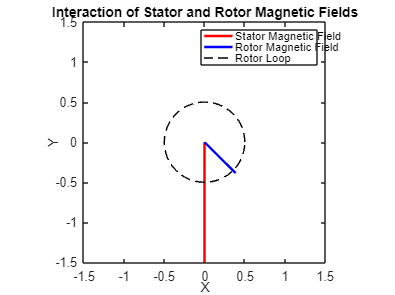

% Set up basic parameters
bmax = 1; % Normalize bmax to 1
freq = 60; % 60 Hz
w = 2*pi*freq; % angular velocity (rad/s)
t = 0:1/6000:1/60;

% Generate the three component magnetic fields of the stator
Baa = sin(w*t) .* (cos(0) + 1i*sin(0));
Bbb = sin(w*t - 2*pi/3) * (cos(2*pi/3) + 1i*sin(2*pi/3));
Bcc = sin(w*t + 2*pi/3) * (cos(-2*pi/3) + 1i*sin(-2*pi/3));

% Calculate the net magnetic field produced by the stator
Bnet_stator = Baa + Bbb + Bcc;

% Parameters for the rotor
rotor_radius = 0.5; % Radius of the rotor loop
rotor_current = 1; % Current in the rotor loop

% Define initial mechanical angle between rotor and stator fields (in radians)
initial_mechanical_angle = pi/4; % Change this value as desired

% Calculate the magnetic field produced by the rotor with the initial mechanical angle
rotor_magnetic_field = zeros(size(t));
for ii = 1:length(t)
    % Magnetic field produced by a current-carrying loop with initial angle
    rotor_magnetic_field(ii) = rotor_current * rotor_radius^2 / (2 * (rotor_radius^2 + (rotor_radius*sin(w*t(ii) - initial_mechanical_angle))^2)^(3/2));
end

% Plot the magnitude and direction of the stator's magnetic field (Bnet_stator)
figure;
for ii = 1:length(t)
    % Plot the stator's rotating magnetic field
    plot([0 real(Bnet_stator(ii))], [0 imag(Bnet_stator(ii))], 'r', 'LineWidth', 2);
    hold on;
    
    % Plot the rotor's magnetic field
    plot([0 rotor_magnetic_field(ii)*cos(w*t(ii) - initial_mechanical_angle)], [0 rotor_magnetic_field(ii)*sin(w*t(ii) - initial_mechanical_angle)], 'b', 'LineWidth', 2);
    
    % Plot rotor loop
    theta = linspace(0, 2*pi, 100);
    x_rotor = rotor_radius * cos(theta);
    y_rotor = rotor_radius * sin(theta);
    plot(x_rotor, y_rotor, 'k--');
    
    axis square;
    axis([-1.5 1.5 -1.5 1.5]);
    xlabel('X');
    ylabel('Y');
    title('Interaction of Stator and Rotor Magnetic Fields');
    legend('Stator Magnetic Field', 'Rotor Magnetic Field', 'Rotor Loop');
    drawnow;
    hold off;
end